%Load Parameters
defaultDir = 'M:\Bergles Lab Data\Papers\In Vivo Paper'; %change if in a different location
cd(defaultDir);
addpath(genpath('MATLAB Functions'));
cd('Supp - Spatial Location');


list = loadFileList('..\Figure 3 - Ablations\Data\WILDTYPE\*\DUP*.tif');
img = loadTif(list{7},16);

[m,n,t] = size(img);
imgR = reshape(img,m*n,t);


## downsample

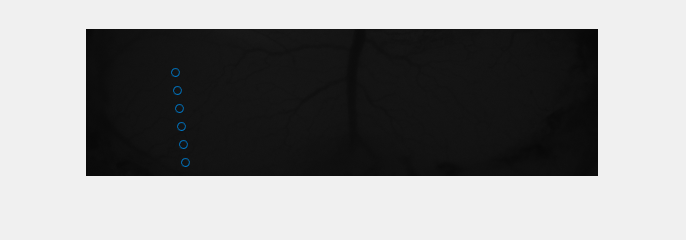


%display image and pick points
figure; imshow(img(:,:,1));
[x,y] = getpts(gcf);
diff_x = round((x(2) - x(1))/(5));
diff_y= round((y(2) - y(1))/(5));
x = round(x:diff_x:x+diff_x*5);
y = round(y:diff_y:y+diff_y*5);
hold on; plot(x,y,'o');



%%
corrImg = [];
for i = 1:size(y,2)
    probe = img((y(i)-3:y(i)+3),(x(i)-3:x(i)+3),:);
    probe = squeeze(mean(mean(probe,1),2));
    
    workingCorr = corr(double(probe),double(imgR)');
    corrImg(:,:,i) = reshape(workingCorr,m,n);
end



## fdas

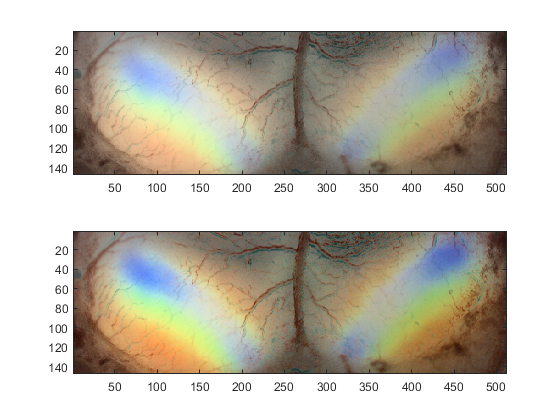


corrRGB = zeros(m,n,3);
%corrRGB(:,:,1) = corrImg(:,:,1)*1.5 + corrImg(:,:,4);
%corrRGB(:,:,2) = corrImg(:,:,2)*1.25 + corrImg(:,:,5);
%corrRGB(:,:,3) = corrImg(:,:,3)*0.75 + corrImg(:,:,6)*1.5;
% corrRGB(:,:,1) = corrImg(:,:,1) + corrImg(:,:,3)/max(max(corrImg(:,:,1) + corrImg(:,:,3)));
% corrRGB(:,:,2) = (corrImg(:,:,5) + corrImg(:,:,3))/max(max(corrImg(:,:,5) + corrImg(:,:,3)));
% corrRGB(:,:,3) = corrImg(:,:,6)/max(max(corrImg(:,:,6)));
thr = 0.0;
 corrRGB(:,:,1) = (corrImg(:,:,5) .* (corrImg(:,:,5) > thr))/max(max(corrImg(:,:,5)));
 corrRGB(:,:,2) = (corrImg(:,:,3) .* (corrImg(:,:,3) > thr))/max(max(corrImg(:,:,3)));
 corrRGB(:,:,3) = (corrImg(:,:,1) .* (corrImg(:,:,1) > thr))/max(max(corrImg(:,:,1)));
figure; subplot(2,1,1); imagesc(corrRGB)
data.corrImg = corrImg; data.corrRGB = corrRGB;

HSV = rgb2hsv(corrRGB);
HSV(:,:,2) = HSV(:, :, 2)*1.5;
HSV(HSV > 1) = 1;  % Limit values
RGB = hsv2rgb(HSV);

subplot(2,1,2); imagesc(RGB);

imwrite(RGB,['.\Data\ICCorrMap.bmp']);


%save([dname '2Pcorr.mat'],'data');

%figure; plot(corrImg(:,:,4))


list = loadFileList('..\Figure 3 - Ablations\Data\WILDTYPE\*\*spatialAnalysis2.mat');

for i=1:size(list,1)
    temp = load(list{i});
    s = fieldnames(temp);
    if i == 1
       eventStruct(1).struct = temp.(s{1});
    else
       eventStruct(i).struct = temp.(s{1});
    end
end

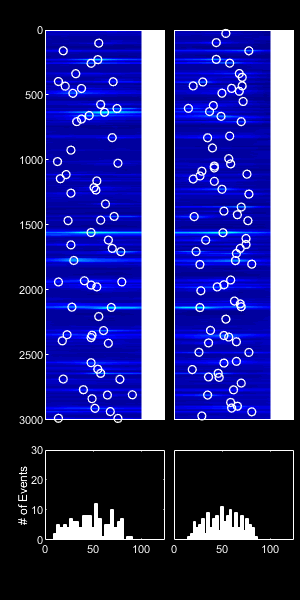

%plot of doobies
load(list{3}); %experiment 342
[peaksBinaryL] = getSpatialPeaks(smLIC,0.02);
[peaksBinaryR] = getSpatialPeaks(smRIC,0.02);

[peakStat, eventStats] = spatialPeakStats(smLIC, peaksBinaryL, smRIC, peaksBinaryR);
plotTimeSeries_dFoF(smLIC, smRIC, peaksBinaryL, peaksBinaryR, peakStat);


    Llocs = find(peaksBinaryL);
    [Lr, Lc] = ind2sub(size(peaksBinaryL),Llocs);
    Rlocs = find(peaksBinaryR);
    [Rr, Rc] = ind2sub(size(peaksBinaryL),Rlocs);
    
    statsL = peakStat{1};
    statsR = peakStat{2};
    histoL = statsL(:,2);
    histoR = statsR(:,2);
    
    lims = [2425 3025]

lims =         2425        3025


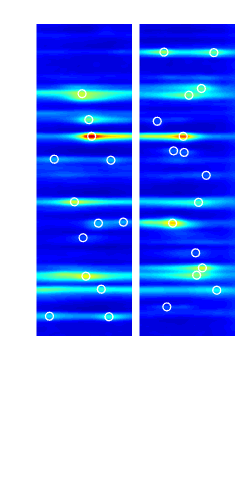

    %single figure for movie
    p = figure('Position',[100 0 300 600]);
    colormap jet;
    pv = [.15 .3 .4 .65];
    subplot('Position',pv);
    imagesc(smLIC');
    caxis([0 0.25]);
    xlim([0 100]);
    ylim(lims);
    hold on; 
    scatter(Lr, Lc,'MarkerEdgeColor','white','LineWidth',1);
    axis off;
    
    pv = [.58 .3 .4 .65];
    subplot('Position',pv);
    imagesc(smRIC');
    caxis([0 0.25]);
    xlim([0 100]);
    ylim(lims);
    hold on; 
    scatter(Rr, Rc,'MarkerEdgeColor','white','LineWidth',1);
   axis off;
    
   figQuality(gcf,gca,[2.5 5])
   print()
   export_fig(['.\EPS Panels\ExampleTrace.eps'],'-eps');
   print(['.\EPS Panels\ExampleTrace.eps'],'-depsc')

%%exemplar
lt_org = [255, 166 , 38]/255;
dk_org = [255, 120, 0]/255;
lt_blue = [50, 175, 242]/255;
dk_blue = [0, 13, 242]/255;
binEdges = [75:50:475];
temp = eventStruct(2).struct

temp = 1×200 struct array with fields:
    eventClassification
    leftOrRightDom
    numPeaks
    domAmp
    maxLamp
    maxRAmp
    xloc
    tloc
    hwx
    hwt
    integral
    lxloc
    rxloc
    delta
    maxLAmp


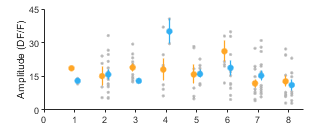

bins = discretize([temp.xloc]*7.65,binEdges);

class = {temp.leftOrRightDom};
leftidx = find(contains(class,'Left'));
rightidx = find(contains(class,'Right'));
tempR = temp(rightidx) ;
tempL = temp(leftidx);
    
start = min(bins); endind = max(bins);
Lmeans = []; Lsterrs=[]; Lfreq = []; Ldelt = [];
Lamps = [tempL.domAmp];
Rmeans = []; Rsterrs=[]; Rfreq = []; Rdelt = [];
Ramps = [tempR.domAmp];
Lbins = discretize([tempL.xloc]*7.65,binEdges);
Rbins = discretize([tempR.xloc]*7.65,binEdges);

for i=start:endind
    indices = find(Lbins == i);
    Lmeans(i) = mean(Lamps(indices));
    Lsterrs(i) = sterr(Lamps(indices),2);
    Lfreq(i) = size(Lamps(indices),2)/10;
   % Ldelt(i) = 
    
    indices = find(Rbins == i);
    Rmeans(i) = mean(Ramps(indices));
    Rsterrs(i) = sterr(Ramps(indices),2);
    Rfreq(i) = size(Ramps(indices),2)/10;
    %Rdelt(i) = 
end

offset = .1;
figure; plot(Lbins-offset,[tempL.domAmp]*100,'.','MarkerSize',5,'Color',[0.7 0.7 0.7]); hold on;
errorbar([start:endind]-offset, Lmeans*100, Lsterrs*100,'LineStyle', 'none','LineWidth',1,'Color',lt_org,'CapSize',0,'Marker','.','MarkerSize',15);
plot(Rbins+offset,[tempR.domAmp]*100,'.','MarkerSize',5,'Color',[0.7 0.7 0.7]);
errorbar([start:endind]+offset, Rmeans*100, Rsterrs*100,'LineStyle', 'none','LineWidth',1,'Color',lt_blue,'CapSize',0,'Marker','.','MarkerSize',15);
ylim([0 45]);
yticks(0:15:45);
xlim([0 8.5]);
ylabel('Amplitude (DF/F)');
figQuality(gcf,gca,[3.5 1.3])
export_fig('.\EPS Panels\indAmpl.eps','-eps')

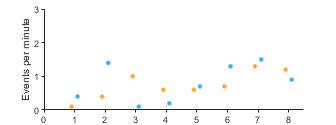


figure;
plot([start:endind]-offset,Lfreq,'.','MarkerSize',10,'Color',lt_org); hold on;
plot([start:endind]+offset,Rfreq,'.','MarkerSize',10,'Color',lt_blue);
ylabel('Events per minute');
ylim([0 3]);
xlim([0 8.5]);
figQuality(gcf,gca,[3.5 1.3])
export_fig('.\EPS Panels\indFreq.eps','-eps')

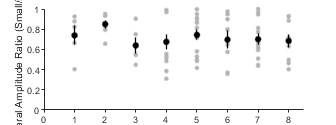


%%% Delta measurements, only bilateral events
biidx = find(contains({temp.eventClassification},'Bi'));
tempBi = temp(biidx);
bins = discretize([tempBi.xloc]*7.65,[75:75:750]);

for i=start:8
    indices = find(bins == i);
    if ~isempty([tempBi(indices).delta])
        meanDeltas(i) = nanmean([tempBi(indices).delta],2);
        sterrDeltas(i) = sterr([tempBi(indices).delta],2);
    else
        meanDeltas(i) = NaN;
        sterrDeltas(i) = NaN;
    end
end

figure;
plot(bins,[tempBi.delta],'.','MarkerSize',10,'Color',[0.7 0.7 0.7]); hold on;
errorbar([start:endind], meanDeltas, sterrDeltas,'LineStyle', 'none','LineWidth',1,'Color','k','CapSize',0,'Marker','.','MarkerSize',15);
ylabel('Bilateral Amplitude Ratio (Small/Large)');
xlim([0 8.5]);
ylim([0 1]);
figQuality(gcf,gca,[3.5 1.3])
export_fig('.\EPS Panels\indDelta.eps','-eps')


% class = {temp.eventClassification};
% biidx = find(contains(class,'Bi'));
% tempBi = temp(biidx);
% figure; histogram(abs([tempBi.rxloc]-[tempBi.lxloc])*(7.64),[0:75:600]); %7.64um/pixel
% xticks([0:75:750])
% xlim([0 525])
% xlabel("Difference in bilateral event location (\mum)");
% ylabel("Number of Events")
% figQuality(gcf,gca,[3.5 1.3])
% 


%group data
Lgroupmeans = zeros(1,8);
Rgroupmeans = zeros(1,8);
Lfreqmeans = [];
Rfreqmeans= [];
binEdges = [75:50:475];
for i = 1:size(eventStruct,2)
    temp = eventStruct(i).struct
    bins = discretize([temp.xloc]*7.65,binEdges);
    
    class = {temp.leftOrRightDom};
    leftidx = find(contains(class,'Left'));
    rightidx = find(contains(class,'Right'));
    tempR = temp(rightidx) ;
    tempL = temp(leftidx);
        
    start = min(bins); endind = max(bins);
    Lmeans = []; Lfreq = []; Ldelt = [];
    Lamps = [tempL.domAmp];
    Rmeans = []; Rsterrs=[]; Rfreq = []; Rdelt = [];
    Ramps = [tempR.domAmp];
    Lbins = discretize([tempL.xloc]*7.65,binEdges);
    Rbins = discretize([tempR.xloc]*7.65,binEdges);
    
    for j=start:8
        indices = find(Lbins == j);
        Lmeans(j) = nanmean(Lamps(indices));
        Lfreq(j) = size(Lamps(indices),2)/10;
        
        indices = find(Rbins == j);
        Rmeans(j) = nanmean(Ramps(indices));
        Rfreq(j) = size(Ramps(indices),2)/10;
    end
    
    Lgroupmeans(i,:) = Lmeans;
    Lfreqmeans(i,:) = Lfreq;
    Rgroupmeans(i,:) = Rmeans;
    Rfreqmeans(i,:) = Rfreq;  
end

temp = 1×213 struct array with fields:
    eventClassification
    leftOrRightDom
    numPeaks
    domAmp
    maxLamp
    maxRAmp
    xloc
    tloc
    hwx
    hwt
    integral
    lxloc
    rxloc
    delta
    maxLAmp


temp = 1×200 struct array with fields:
    eventClassification
    leftOrRightDom
    numPeaks
    domAmp
    maxLamp
    maxRAmp
    xloc
    tloc
    hwx
    hwt
    integral
    lxloc
    rxloc
    delta
    maxLAmp


temp = 1×183 struct array with fields:
    eventClassification
    leftOrRightDom
    numPeaks
    domAmp
    maxLamp
    maxRAmp
    xloc
    tloc
    hwx
    hwt
    integral
    lxloc
    rxloc
    delta
    maxLAmp


temp = 1×218 struct array with fields:
    eventClassification
    leftOrRightDom
    numPeaks
    domAmp
    maxLamp
    maxRAmp
    xloc
    tloc
    hwx
    hwt
    integral
    lxloc
    rxloc
    delta
    maxLAmp


temp = 1×165 struct array with fields:
    eventClassification
    leftOrRightDom
    numPeaks
    domAmp
    maxLamp
    maxRAmp
    xloc
    tloc
    hwx
    hwt
    integral
    lxloc
    rxloc
    delta
    maxLAmp


temp = 1×160 struct array with fields:
    eventClassification
    leftOrRightDom
    numPeaks
    domAmp
    maxLamp
    maxRAmp
    xloc
    tloc
    hwx
    hwt
    integral
    lxloc
    rxloc
    delta
    maxLAmp


temp = 1×181 struct array with fields:
    eventClassification
    leftOrRightDom
    numPeaks
    domAmp
    maxLamp
    maxRAmp
    xloc
    tloc
    hwx
    hwt
    integral
    lxloc
    rxloc
    delta
    maxLAmp



Lgm = nanmean(Lgroupmeans,1);
Lgsterr = sterr(Lgroupmeans,1)

Lgsterr =     0.0143    0.0254    0.0118    0.0172    0.0163    0.0191    0.0209    0.0132


Rgm = nanmean(Rgroupmeans,1)

Rgm =     0.1550    0.1882    0.1896    0.2233    0.1981    0.1912    0.2116    0.1522


Rgsterr = sterr(Rgroupmeans,1)

Rgsterr =     0.0259    0.0187    0.0221    0.0369    0.0363    0.0128    0.0289    0.0192


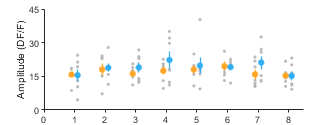


offset = .1;
figure; plot([start:8]-offset,Lgroupmeans*100,'.','MarkerSize',5,'Color',[0.7 0.7 0.7]); hold on;
errorbar([start:8]-offset, Lgm*100, Lgsterr*100,'LineStyle', 'none','LineWidth',1,'Color',lt_org,'CapSize',0,'Marker','.','MarkerSize',15); hold on;
plot([start:8]+offset,Rgroupmeans*100,'.','MarkerSize',5,'Color',[0.7 0.7 0.7]);
errorbar([start:8]+offset, Rgm*100, Rgsterr*100,'LineStyle', 'none','LineWidth',1,'Color',lt_blue,'CapSize',0,'Marker','.','MarkerSize',15);
xlim([0 8.5]);
ylim([0 45]);
yticks(0:15:45);
ylabel('Amplitude (DF/F)');
figQuality(gcf,gca,[3.5 1.3])
export_fig('.\EPS Panels\groupAmplitudes.eps','-eps')


Lgf = nanmean(Lfreqmeans,1);
Lgfsterr = sterr(Lfreqmeans,1)

Lgfsterr =     0.1149    0.1512    0.1232    0.0685    0.0976    0.1209    0.0680    0.0808


Rgf = nanmean(Rfreqmeans,1)

Rgf =     0.3000    0.8286    0.5714    0.6857    0.7714    1.2000    0.8000    1.1286


Rgfsterr = sterr(Rfreqmeans,1)

Rgfsterr =     0.0787    0.1286    0.1459    0.1639    0.0680    0.0900    0.1195    0.1554


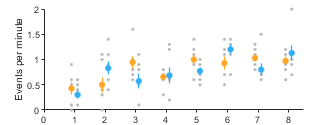


figure;
plot([start:8]-offset,Lfreqmeans,'.','MarkerSize',5,'Color',[0.7 0.7 0.7]); hold on;
errorbar([start:8]-offset, Lgf, Lgfsterr,'LineStyle', 'none','LineWidth',1,'Color',lt_org,'CapSize',0,'Marker','.','MarkerSize',15);
plot([start:8]+offset,Rfreqmeans,'.','MarkerSize',5,'Color',[0.7 0.7 0.7]);
errorbar([start:8]+offset, Rgf, Rgfsterr,'LineStyle', 'none','LineWidth',1,'Color',lt_blue,'CapSize',0,'Marker','.','MarkerSize',15);
xlim([0 8.5])
ylabel('Events per minute');
ylim([0 2]);
figQuality(gcf,gca,[3.5 1.3]);
export_fig('.\EPS Panels\groupFreq.eps','-eps')

%Same analysis, but no LR comparison
%%exemplar
lt_org = [255, 166 , 38]/255;
dk_org = [255, 120, 0]/255;
lt_blue = [50, 175, 242]/255;
dk_blue = [0, 13, 242]/255;
binEdges = [75:50:475];
dims = [2.5 1]

dims =     2.5000    1.0000


temp = eventStruct(3).struct

temp = 1×183 struct array with fields:
    eventClassification
    leftOrRightDom
    numPeaks
    domAmp
    maxLamp
    maxRAmp
    xloc
    tloc
    hwx
    hwt
    integral
    lxloc
    rxloc
    delta
    maxLAmp


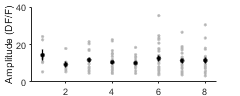

bins = discretize([temp.xloc]*7.65,binEdges);
    
start = min(bins); endind = max(bins);
means = []; sterrs=[]; freq = []; delt = [];
amps = [temp.domAmp];

for i=start:endind
    indices = find(bins == i);
    means(i) = mean(amps(indices));
    sterrs(i) = sterr(amps(indices),2);
    freq(i) = size(amps(indices),2)/10;
end

offset = .1;
figure; plot(bins,[temp.domAmp]*100,'.','MarkerSize',5,'Color',[0.7 0.7 0.7]); hold on;
errorbar([start:endind], means*100, sterrs*100,'LineStyle', 'none','LineWidth',1,'Color','k','CapSize',0,'Marker','.','MarkerSize',10);
ylim([0 40]);
yticks(0:20:40);
xlim([.5 8.5]);
ylabel('Amplitude (DF/F)');
figQuality(gcf,gca,dims)
export_fig('.\EPS Panels\indAmpl.eps','-eps')

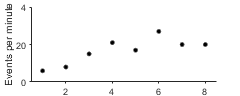



figure;
plot([start:endind],freq,'.','MarkerSize',10,'Color','k'); hold on;
ylabel('Events per minute');
ylim([0 4]);
yticks([0:2:4]);
yticklabels({'0','20','4'});
xlim([0.5 8.5]);
figQuality(gcf,gca,dims)
export_fig('.\EPS Panels\indFreq.eps','-eps')

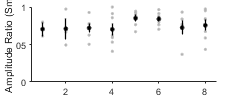

% 
%%% Delta measurements, only bilateral events
biidx = find(contains({temp.eventClassification},'Bi'));
tempBi = temp(biidx);
bins = discretize([tempBi.xloc]*7.65,binEdges);

for i=start:8
    indices = find(bins == i);
    if ~isempty([tempBi(indices).delta])
        meanDeltas(i) = nanmean([tempBi(indices).delta],2);
        sterrDeltas(i) = sterr([tempBi(indices).delta],2);
    else
        meanDeltas(i) = NaN;
        sterrDeltas(i) = NaN;
    end
end

figure;
plot(bins,[tempBi.delta],'.','MarkerSize',5,'Color',[0.7 0.7 0.7]); hold on;
errorbar([start:endind], meanDeltas, sterrDeltas,'LineStyle', 'none','LineWidth',1,'Color','k','CapSize',0,'Marker','.','MarkerSize',10);
ylabel('Bilateral Amplitude Ratio (Small/Large)');
xlim([0.5 8.5]);
ylim([0 1]);
yticklabels({'0','05','1'})
yticks([0:.5:1]);
figQuality(gcf,gca,dims)
export_fig('.\EPS Panels\indDelta.eps','-eps')

## Group

%group data
groupmeans = zeros(1,8);
freqmeans = [];
binEdges = [75:50:475];
dims = [2.5 1]

dims =     2.5000    1.0000


for i = 1:size(eventStruct,2)
    temp = eventStruct(i).struct
    bins = discretize([temp.xloc]*7.65,binEdges);
    
    start = min(bins); endind = max(bins);
    means = []; freq = [];
    amps = [temp.domAmp];

    for j=start:8
        indices = find(bins == j);
        means(j) = nanmean(amps(indices));
        freq(j) = size(amps(indices),2)/10;
    end
    
    biidx = find(contains({temp.eventClassification},'Bi'));
    tempBi = temp(biidx);
    bins = discretize([tempBi.xloc]*7.65,binEdges);
    deltas = [];
    for j=start:8
        indices = find(bins == j);
        if ~isempty([tempBi(indices).delta])
            deltas(j) = nanmean([tempBi(indices).delta],2);
        else
            deltas(j) = NaN;
        end
    end
    
    groupmeans(i,:) = means;
    freqmeans(i,:) = freq;
    deltameans(i,:) = deltas;
end

temp = 1×213 struct array with fields:
    eventClassification
    leftOrRightDom
    numPeaks
    domAmp
    maxLamp
    maxRAmp
    xloc
    tloc
    hwx
    hwt
    integral
    lxloc
    rxloc
    delta
    maxLAmp


temp = 1×200 struct array with fields:
    eventClassification
    leftOrRightDom
    numPeaks
    domAmp
    maxLamp
    maxRAmp
    xloc
    tloc
    hwx
    hwt
    integral
    lxloc
    rxloc
    delta
    maxLAmp


temp = 1×183 struct array with fields:
    eventClassification
    leftOrRightDom
    numPeaks
    domAmp
    maxLamp
    maxRAmp
    xloc
    tloc
    hwx
    hwt
    integral
    lxloc
    rxloc
    delta
    maxLAmp


temp = 1×218 struct array with fields:
    eventClassification
    leftOrRightDom
    numPeaks
    domAmp
    maxLamp
    maxRAmp
    xloc
    tloc
    hwx
    hwt
    integral
    lxloc
    rxloc
    delta
    maxLAmp


temp = 1×165 struct array with fields:
    eventClassification
    leftOrRightDom
    numPeaks
    domAmp
    maxLamp
    maxRAmp
    xloc
    tloc
    hwx
    hwt
    integral
    lxloc
    rxloc
    delta
    maxLAmp


temp = 1×160 struct array with fields:
    eventClassification
    leftOrRightDom
    numPeaks
    domAmp
    maxLamp
    maxRAmp
    xloc
    tloc
    hwx
    hwt
    integral
    lxloc
    rxloc
    delta
    maxLAmp


temp = 1×181 struct array with fields:
    eventClassification
    leftOrRightDom
    numPeaks
    domAmp
    maxLamp
    maxRAmp
    xloc
    tloc
    hwx
    hwt
    integral
    lxloc
    rxloc
    delta
    maxLAmp



gm = nanmean(groupmeans,1);
gsterr = sterr(groupmeans,1)

gsterr =     0.0137    0.0193    0.0129    0.0177    0.0229    0.0136    0.0222    0.0147


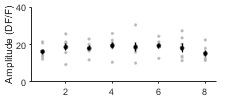



offset = .1;
figure; plot([start:8],groupmeans*100,'.','MarkerSize',5,'Color',[0.7 0.7 0.7]); hold on;
errorbar([start:8], gm*100, gsterr*100,'LineStyle', 'none','LineWidth',1,'Color','k','CapSize',0,'Marker','.','MarkerSize',10); hold on;
xlim([0.5 8.5]);
ylim([0 40]);
yticks(0:20:40);
ylabel('Amplitude (DF/F)');
figQuality(gcf,gca,dims)
export_fig('.\EPS Panels\groupAmplitudes.eps','-eps')


gf = nanmean(freqmeans,1);
gfsterr = sterr(freqmeans,1)

gfsterr =     0.1643    0.2368    0.2052    0.2192    0.1229    0.1822    0.1742    0.1826


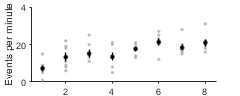


figure;
plot([start:8],freqmeans,'.','MarkerSize',5,'Color',[0.7 0.7 0.7]); hold on;
errorbar([start:8], gf, gfsterr,'LineStyle', 'none','LineWidth',1,'Color','k','CapSize',0,'Marker','.','MarkerSize',10);
xlim([0.5 8.5])
ylabel('Events per minute');
ylim([0 4]);
yticks([0:2:4]);
yticklabels({'0','20','4'})
figQuality(gcf,gca,dims);
export_fig('.\EPS Panels\groupFreq.eps','-eps')


gd = nanmean(deltameans,1);
gdsterr = sterr(deltameans,1)

gdsterr =     0.0386    0.0216    0.0413    0.0170    0.0356    0.0503    0.0181    0.0110


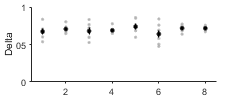


figure;
plot([start:8],deltameans,'.','MarkerSize',5,'Color',[0.7 0.7 0.7]); hold on;
errorbar([start:8], gd, gdsterr,'LineStyle', 'none','LineWidth',1,'Color','k','CapSize',0,'Marker','.','MarkerSize',10);
xlim([0.5 8.5])
ylabel('Delta');
ylim([0 1]);
yticklabels({'0','05','1'})
yticks([0:.5:1]);
figQuality(gcf,gca,dims);
export_fig('.\EPS Panels\groupDelta.eps','-eps')

## Look at distribution of events

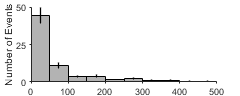


counts = [];
for i=1:size(eventStruct,2)
    temp = eventStruct(i).struct;
    class = {temp.eventClassification};
    biidx = find(contains(class,'Bi'));
    temp = temp(biidx);
    [n,edges] = histcounts(abs([temp.rxloc]-[temp.lxloc])*(7.64),[0:50:600]); %7.64um/pixel
    counts(i,:) = n;
end

figure;
histogram('BinEdges',edges,'BinCounts',mean(counts,1),'FaceAlpha',1,'FaceColor',[0.7 0.7 0.7]); hold on;
errorbar([25:50:600],mean(counts,1),sterr(counts,1),'CapSize',0,'LineStyle', 'none', 'LineWidth', 1, 'Color','k');
ylabel('Number of Events')
xlim([0 500]);
ylim([0 50]);
yticks([0:25:150])
figQuality(gcf,gca,dims);
export_fig('.\EPS Panels\groupDiff.eps','-eps')

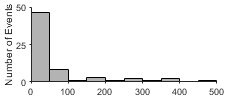


figure;
histogram('BinEdges',edges,'BinCounts',counts(3,:),'FaceAlpha',1,'FaceColor',[0.7 0.7 0.7]); hold on;
ylabel('Number of Events')
xlim([0 500]);
ylim([0 50]);
yticks([0:25:150])
figQuality(gcf,gca,dims);
export_fig('.\EPS Panels\indDiff.eps','-eps')

%%look at deltas for each event along tonotopic axis
%%delta example
list = loadFileList('..\Figure 3 - Ablations\Data\WILDTYPE\*\*spatialAnalysis2.mat');
    temp = load(list{2});
    s = fieldnames(temp);
    smLIC = temp.(s{3});
    smRIC = temp.(s{4});
   
    temp = temp.(s{1})

temp = 1×200 struct array with fields:
    eventClassification
    leftOrRightDom
    numPeaks
    domAmp
    maxLamp
    maxRAmp
    xloc
    tloc
    hwx
    hwt
    integral
    lxloc
    rxloc
    delta
    maxLAmp


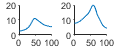

    class = {temp.eventClassification};
    biidx = find(contains(class,'Bi'));
    temp = temp(biidx);
    offset = 16;
    
    figure;
    subplot(1,2,1);
     plot(smLIC(:,temp(17).tloc)*100);
     ylim([0 20]);
     box off;
     subplot(1,2,2);
     plot(smRIC(:,temp(17).tloc)*100);
     ylim([0 20])
     figQuality(gcf,gca,[1.3 0.5])
     export_fig('.\EPS Panels\exDF.eps','-eps')

%end


%explore dataset bilateral
list = loadFileList('..\Figure 3 - Ablations\Data\WILDTYPE\*\*spatialAnalysis2.mat');
temp = load(list{4});
s = fieldnames(temp);
smLIC = temp.(s{3});
smRIC = temp.(s{4});

temp = temp.(s{1})

temp = 1×218 struct array with fields:
    eventClassification
    leftOrRightDom
    numPeaks
    domAmp
    maxLamp
    maxRAmp
    xloc
    tloc
    hwx
    hwt
    integral
    lxloc
    rxloc
    delta
    maxLAmp


class = {temp.eventClassification};
biidx = find(contains(class,'Bi'));
temp = temp(biidx);
    
size([temp([temp.xloc] < 40)])

ans =      1    26


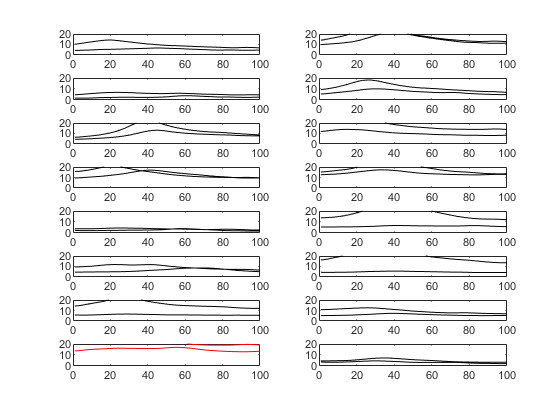

ans = 189

ans = 222

ans = 468

ans = 857

ans = 1097

ans = 1288

ans = 1789

ans = 2040

ans = 2176

ans = 2253

ans = 2275

ans = 2454

ans = 2474

ans = 2590

ans = 2632

ans = 3026

temp2 = temp([temp.xloc] < 40);
figure;
for i=1:16
    subplot(8,2,i);
    temp2(i).tloc
    if temp2(i).numPeaks > 1
    plot(smLIC(:,temp2(i).tloc)*100,'Color','r'); hold on;
    plot(flipud(smRIC(:,temp2(i).tloc))*100,'Color','r')
    ylim([0 20])
    else
        plot(smLIC(:,temp2(i).tloc)*100,'Color','k'); hold on;
    plot(flipud(smRIC(:,temp2(i).tloc)*100),'Color','k')
    ylim([0 20])
    end
end